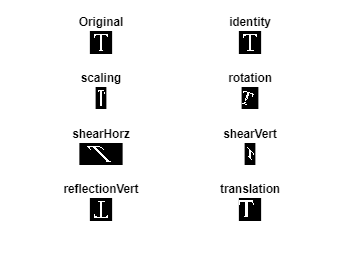

figure
hold on
showaxes('boxoff')

% [haletterT, posletterT] = tight_subplot(4,2,[-0.0001 -0.0001]);

letterT = imread("imageT.png");
letterT = rgb2gray(letterT);

% axes(haletterT(1));
subplot(4,2,1);imshow(letterT), title("Original")

imgT1 = identity(letterT);
% axes(haletterT(2));
subplot(4,2,2);imshow(imgT1), title("identity")

imgT2 = scaling(2,1,letterT);
% axes(haletterT(3));
subplot(4,2,3);imshow(imgT2), title("scaling")

imgT3 = rotation(20,letterT);
% axes(haletterT(4));
subplot(4,2,4);imshow(imgT3), title("rotation")

imgT4 = shearHorz(1,letterT);
% axes(haletterT(5));
subplot(4,2,5);imshow(imgT4), title("shearHorz")

imgT5 = shearVert(1,letterT);
% axes(haletterT(6));
subplot(4,2,6);imshow(imgT5), title("shearVert")

imgT6 = reflectionVert(letterT);
% axes(haletterT(7));
subplot(4,2,7);imshow(imgT6), title("reflectionVert")

imgT7 = translation(-10,-50,letterT);
% axes(haletterT(8));
subplot(4,2,8);imshow(imgT7), title("translation")

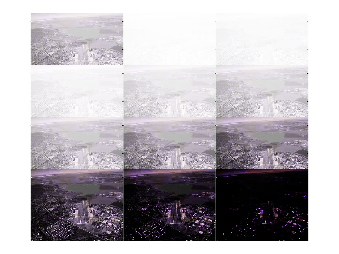

% Gamma transformations
figure
aerea = imread("aerea.png");

gamma = [0.04 0.10 0.20 0.40 0.67 1.00 1.50 2.50 5.00 10.0 25.0];

figure
showaxes('boxoff')
[ha, pos] = tight_subplot(4,3,[-0.08 -0.08]);

axes(ha(1))
imshow(aerea);

for gammaIndex=1:length(gamma)
    gammaImage = gammaTransformation(double(aerea)/255,1,gamma(gammaIndex));
    axes(ha(gammaIndex+1));
    imshow(gammaImage)
end



figure

hold on
for gammaIndex=1:length(gamma)
    gammaImage = gammaTransformation(double(aerea)/255,1,gamma(gammaIndex));
    uniqueValuesGammaImage = unique(gammaImage);
    uniqueValuesOriginalImage = unique(aerea);
    labelname = "γ = " + gamma(gammaIndex);
    plot(uniqueValuesOriginalImage,uniqueValuesGammaImage,'DisplayName',labelname)
    xlim([0 255])
end
lgd = legend('FontSize',7,'Box','off','Location','eastoutside');
hold off

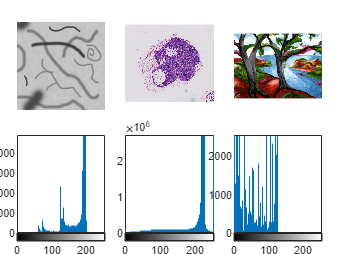

figure

[ha, pos] = tight_subplot(2,3,[0.06 0.06]);

threads = imread("threads.png");
% subplot(2,3,1);
axes(ha(1));
imshow(threads)
% subplot(2,3,4);
axes(ha(4));
imhist(threads);

tumor_091R = imread("tumor_091R.tif");
% subplot(2,3,2);
axes(ha(2));
imshow(tumor_091R);
% subplot(2,3,5);
axes(ha(5));
imhist(tumor_091R);

[trees,map] = imread("trees.tif");
% subplot(2,3,3);
axes(ha(3));
imshow(trees,map);
% subplot(2,3,6);
axes(ha(6));
imhist(trees);

function [imgT] = gammaTransformation(image, c, gamma)

    [sy,sx,sz] = size(image);
    imgT = zeros(sy,sx,sz);
    for z=1:sz
        for y=1:sy
            for x=1:sx
                r = image(y,x,z);
                s = power(c*r,gamma);
                imgT(y,x,z) = s;
            end
        end
    end
end

-

function [imgT] = identity(image)

    [sy,sx] = size(image);
    imgT = zeros(sy,sx);

    for v=1:sy
        for w=1:sx 
            x = w;
            y = v;
            imgT(y,x) = image(v,w);
        end
    end            

end

-

function [imgT] = scaling(cy,cx, image)

    [sy,sx] = size(image);
    imgT = zeros(sy,sx);

    for v=1:sy
        for w=1:sx
            x = ceil(cx*w);
            y = ceil(cy*v);
            areaY = ceil(y-cy/2:y+cy/2);
            areaX = ceil(x-cx/2:x+cx/2);
            imgT(areaY,areaX) = image(v,w);
        end
    end

end

-

function [imgT] = rotation(degree,image)
    
    [sy,sx] = size(image);
    imgT = zeros(sy,sx);
    
    for v=1:sy
        for w=1:sx
            x = ceil(w*cosd(degree) - v*sind(degree));
            y = ceil(w*sind(degree) + v*cosd(degree));
            if x > 0 &&  y > 0
                imgT(y,x) = image(v,w);
            end
 
            

        end
    end

end

-

function [imgT] = shearHorz(alpha,image)

    [sy,sx] = size(image);
    imgT = zeros(sy,sx);

    for v=1:sy
        for w=1:sx

            x = ceil(w + alpha*v);
            y = v;

            if x > 0
                imgT(y,x) = image(v,w);
            end

        end
    end

end

-

function [imgT] = shearVert(beta,image)

    [sy,sx] = size(image);
    imgT = zeros(sy,sx);

    for v=1:sy
        for w=1:sx
            
            x = w;
            y = ceil(beta*w + v);
            
            if y > 0
                imgT(y,x) = image(v,w);
            
            end
        end
    end
end

-

% function [imgT] = reflectionHorz(image)
% 
%     [sy,sx] = size(image);
%     imgT = zeros(sy,sx);
% 
%     for v=1:sy
%         for w=1:sx
%             x = sx-w+1;
%             y = v;
%             imgT(y,x) = image(v,w);
%         end
%     end
% end

-

function [imgT] = reflectionVert(image)

    [sy,sx] = size(image);
    imgT = zeros(sy,sx);

    for v=1:sy
        for w=1:sx
            x = w;
            y = sy-v+1;
            imgT(y,x) = image(v,w);
        end
    end
end

-

function [imgT] = translation(translation_y,translation_x,image)

    [sy,sx] = size(image);
    imgT = zeros(sy,sx);

    for v=1:sy
        for w=1:sx
            x = w + translation_x;
            y = v + translation_y;
            if x > 0 && y > 0
                imgT(y,x) = image(v,w);
            end
        end
    end
end